# Fixed-Point Implementation of Digital Filters

Dear Students, 

Welcome to Lab 6!

In  the previous lab, you have explored how the pole-zero locations and frequency responses change due to quantization of the coefficients. In this lab, we will implement filters in the digital domain, where both the input data and the filter coefficients are quantized. 

### Learning Outcomes: 

At the end of the lab, you will be able to

- Implement a filter using fixed-point representations. 

- Explain about the limit-cycle behaviour of the filters in fixed point implementations. 

### Reference: 

"A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall", 2nd or 3rd Edition. 

## IIR Filter Implementation: 

Suppose you want to implement the following filter: $y[n] = ay[n-1]+x[n],\;\forall n\geq 1, y[0] = 0, $using $8$-bit register to store $a, x[n], y[n]$. Let $a = 0.5. $ In the binary notation, $a = 0.100000_2$. However, we cannot store a binary  point in the fixed point register and operate it in a fixed-point processor. Hence, if we store the bits for $a$, **the fixed-point processor sees it as,  **$a = 0100000_2 = 64_{10}.
$ **You as a programmer should remember where the binary point actually is. **In the above case, you as a programmer know that the decimal number represented by the register is actually, $\frac{64}{2^7} = 0.5, $ as the binary point has to be shifted towards right by $7$ places. 

In Matlab, what an 8-bit fixed-point register sees can be represented using the *integer* data types (see [https://in.mathworks.com/help/matlab/matlab_prog/integers.html)](https://in.mathworks.com/help/matlab/matlab_prog/integers.html))

Now, consider the following $a$ vector. 

If you store this in an 8-bit fixed-point register, what values will a fixed-point processor see? Here is the answer. 

 %% Answer
 a  = 0:0.001:1

a =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


 ValuesSeenbyComputer = int8(a*2^7); 


  In the above, we are manually doing what a fixed-point processor would have done, i.e., shifting the binary point by 7 locations to the right.  (Note that since the processor we are using is not a fixed point processor  and we can represent the floating point numbers given by $a$ directly. However, for the learning purpose, we are trying to imitate what a fixed-point processor would have done). 

Let us now create a signal, named $x[n]$,  which will act an the input to our filter. Please do not worry as to how the below $x[n]$ is generated. 

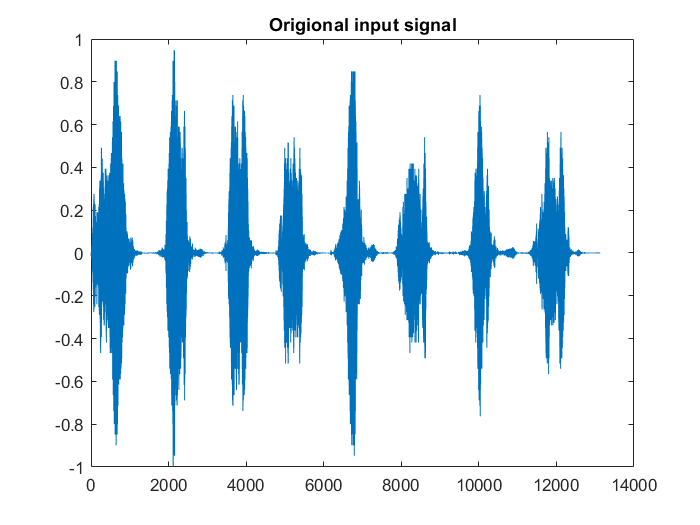

load chirp.mat % It stores the output in y and Fs gives the sampling frequency. 
%sound(y, Fs)  % If required, you can play the sound. 
x = y + 0.2*randn(length(y),1); % We have corrupted it with a Gaussian noise;
x =  x/(max(x)+0.0001); % gaurantee that the input is less than 1. 
plot(y); % Original Signal
title("Origional input signal")

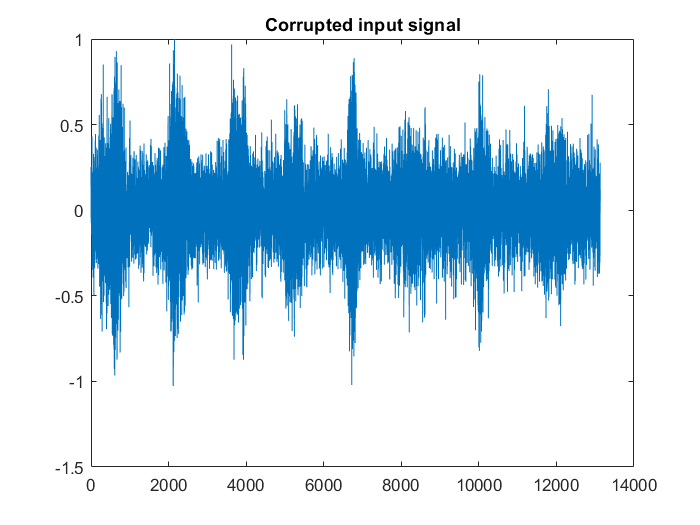

plot(x); % Corrupted Signal, which will act as the input. 
title("Corrupted input signal")

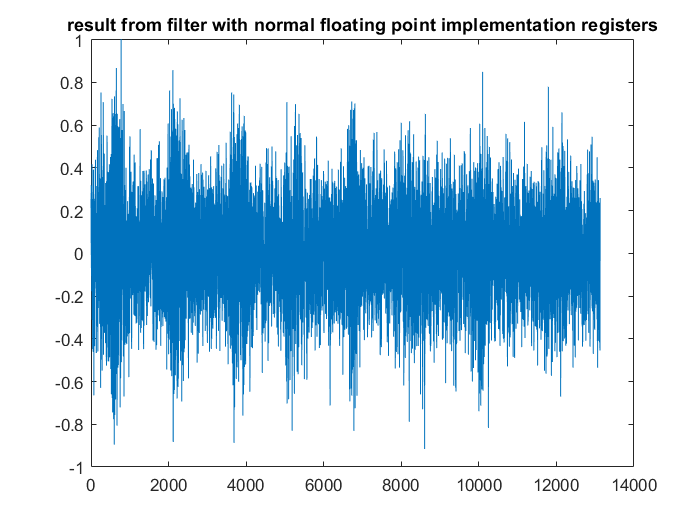

%Filtered signal with normal floating implementation To compare with the
%non floating implementations
FilterOutput(1) =  0;
for i=2:length(x)
    FilterOutput(i)=0.5*FilterOutput(i-1)+x(i-1); %as values start from index 1 in x .
end
FilterOutput=FilterOutput(2:end);%To remove the first element added for defining y[n-1] for the first data value.
plot(FilterOutput);
title("result from filter with normal floating point implementation registers")

%sound(FilterOutput,Fs);pause(2);


### Question (60 Points): 

 In the below, filter *x, *with $y[n] = ay[n-1]+x[n],\;\forall n\geq 2, y[1] = 0, $ using 8-bit registers for storing $a, x[n], y[n]$ and product $ay[n-1]$. 

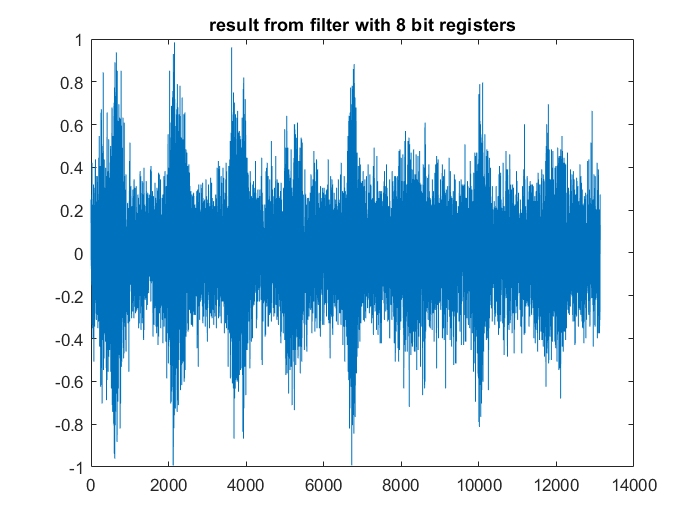

aFixedPoint = int8(0.5*2^7); % the  value of a=0.5 seen by a 8-bit fixed point processor. 
xFixedPoint =  int8(x*2^7); % FILL IN THE BLANKS. The values of x seen by a 8-bit fixed point processor. 
FilterOutput(1) =  0; % The output, y[n], of the filter. 

for i = 2: length(xFixedPoint)+1
    %We have to divide the product by 2^7 otherwise we will always have
    %value 128 as the 8 bit integer as the floating point approximation
    %will take the maximum pssible value as the value and that will lead to
    %wrong results.
    FilterOutput(i) = int8( int8(aFixedPoint*FilterOutput(i-1)/2^7)+xFixedPoint(i-1));  % FILL IN THE BLANKS. Implement y[n] = ay[n-1]+x[n] here. 
                            % Your output of the multiplier must be represented in the 8-bit fixed-point representation
                            % Your summation must also be done using 8-bit fixed-point arithmetic.   
                            % Pay special attention to what happens when to the binary point location when
                            % you multiply. 
end
FilterOutput=FilterOutput(2:end);%To remove the first element added for defining y[n-1] for the first data value.
%TO get the filtered data in actual floating oint representation.
FilterOutput=FilterOutput/2^7;
plot(FilterOutput);
title("result from filter with 8 bit registers")

%sound(FilterOutput,Fs)

Now, perform the above filtering using 16-bit registers. 

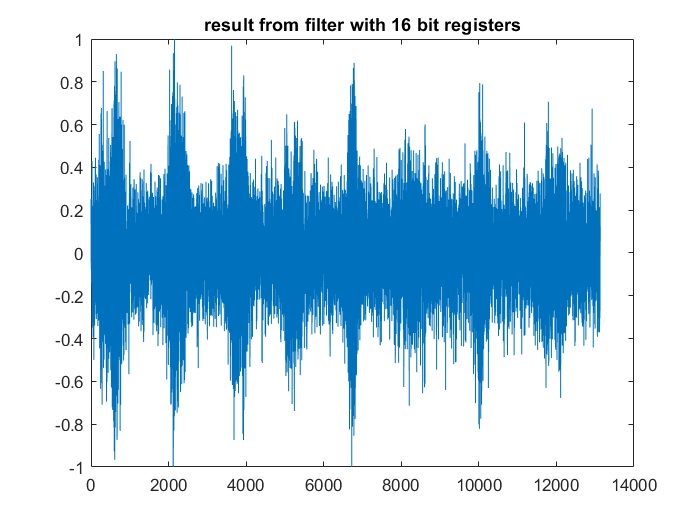

aFixedPoint = int16(0.5*2^15); % the value of a=0.5 seen by a 16-bit fixed point processor. 
xFixedPoint =  int16(x*2^15); % FILL IN THE BLANKS the values of x seen by a 16-bit fixed point processor. 
FilterOutput(1) =  0; % the output, y[n], of the filter. 

for i = 2: length(xFixedPoint)+1
    %We have to divide the product by 2^15 otherwise we will always have
    %value of 16 bit integer as the floating point approximation
    %will take the maximum pssible value as the value and that will lead to
    %wrong results.
    FilterOutput(i) =  int16( int16(aFixedPoint*FilterOutput(i-1)/2^15)+xFixedPoint(i-1));   
end
FilterOutput=FilterOutput(2:end);%To remove the first element added for defining y[n-1] for the first data value.
%TO get the filtered data in actual floating oint representation.
FilterOutput=FilterOutput/2^15;
plot(FilterOutput);
title("result from filter with 16 bit registers")

%sound(FilterOutput,Fs)

Now, perform the above filtering using 32-bit registers. 

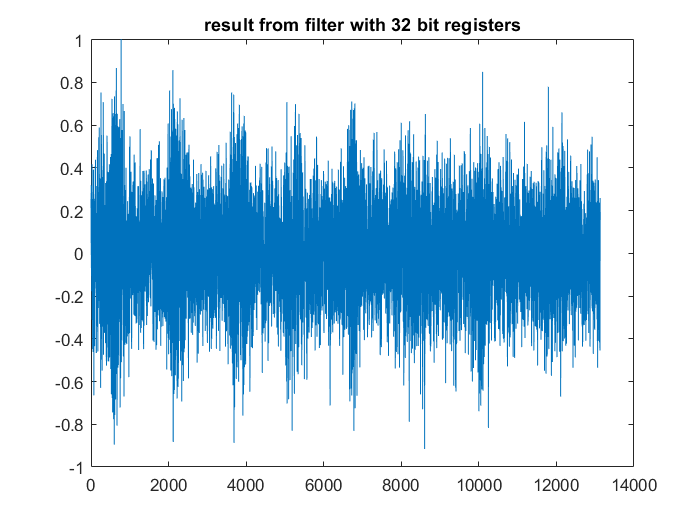

aFixedPoint = int32(0.5*2^15); % the value of a=0.5 seen by a 32-bit fixed point processor. 
xFixedPoint = int32(x*2^15); % FILL IN THE BLANKS the values of x seen by a 32-bit fixed point processor. 
FilterOutput(1) =  0; % the output, y[n], of the filter. 

for i = 2: length(xFixedPoint)+1
    %Here since we don't need too many digits after decimal we can manage
    %with just 5 digits by using 2^15 so this way we don't loose anything
    %even after multiplying two such numbers as they are well within range
    %for 32 bit integers but to ensure the values are at same power we have to multiply the y[n-1] term by 2^15 otherwise it is scaled down. 
    %But for the final term its again crossing 32 bits so we have to
    %downscale it to ensure we don't loose data.
    FilterOutput(i) =  int32(( int32(aFixedPoint*FilterOutput(i-1))+xFixedPoint(i-1)*2^15)/2^15);    
end
FilterOutput=FilterOutput(2:end);%To remove the first element added for defining y[n-1] for the first data value.
%To get the filtered data in actual floating oint representation.
FilterOutput=FilterOutput/2^15;
plot(FilterOutput);
title("result from filter with 32 bit registers")

%sound(FilterOutput,Fs)

#### Answer the following: 

Observe the ouputs in the above 3 cases and make your comments (this is somewhat a open-ended question. You can decide what you want to comment on). 

*ANSWER:  When we compare the output plots with the normal floating point we can see that the 32 bit one resempbes most closely to the one plotted directly using double precision. Then if we look at the sharpness (number of vertical edges for a particular value of x)it's increasing with increasing the number of bits used to do the computation so does quality of filtered signal. So with all this we get that to get the best output with 32 bit integer implementation. Though that is not resonably appreciated while listening but maybe the audio expecrts might hear difference.*

## Limit-Cycle Behavior:  

Now, study Example 6.13 in the 2nd Edition of the textbook (or equivalently, Example 6.15 in the 3rd Edition of the textbook). For the example,  we have already written the code:  

### When a = 0.5 using 8-bit Fixed-Point Implementation

fprintf("Implementation for a=0.5")

Implementation for a=0.5

a =  int8(64);      
x = [0 int8(112) zeros(1,20)];
y=[zeros(1,20)]; %To remove junk data from y to make understanding simpler
y(1) = int8(0); 
for i = 2:20
    y(i) = a*y(i-1)/2^7 + x(i)
   
end

y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0


y =      0   112     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


### When a =  - 0.5 using 8-bit Fixed-Point Implementation

fprintf("Implementation for a=-0.5")

Implementation for a=-0.5

a =  int8(-64);      
x = [0 int8(112) zeros(1,20)];
y=[zeros(1,20)]; %To remove junk data from y
y(1) = int8(0); 
for i = 2:20
    y(i) = a*y(i-1)/2^7 + x(i)
   
end

y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     0     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1     0     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     0     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1     0     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     0     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     0     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     0     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     0     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     0     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     0     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     0


y =      0   112    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1


### Other possible solution:

fprintf("Another possible solution for limit cycle")

Another possible solution for limit cycle

if int8(2^6/a)==1 || int8(2^6/a)==-1 %Only when the multiplication factor might lead to limit cycle
    a =  int16(a);      
    x = [0 int16(112) zeros(1,20)];
    y=[zeros(1,20)]; %To remove junk data from y
    y(1) = int16(0); 
    for i = 2:20
        y(i) = a*y(i-1)/2^15 + x(i)
       
    end
end

y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0   112     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


### Question (40 Points): 

Now study the above codes and their outputs and make your comments, especially on the following points. 

- What is the limit cycle behavior? Why does it occur? 

- How can we avoid limit cycles? 

- Any other comments? 

*ANSWER:  Limit cycle behavior is repetition or Oscillation of results from a filter even if the input is 0 ie. the result gets stuck at some particuar value and doesn't go to 0 even after input is now 0. It can be caused by sucessive round-offs or truncation of  products in an iterated difference equation as occured from y[3] onwards here.*

*Here the result  shall be 56 ~ *${\left(111000\right)}_2$ and -56 for y[3] but its stuck at 1 for a=+64 and oscillated between +1,-1 for a=-64.

now the result 1 which is actually stored is  0.000001 whose decimal equivalent is 0.015625 or 1/64.  when it's multiplied by 64 gives 1 again and then on dividing by 2^7 will again store the same thing as 0.000001 but since no decimal points are stored the result stays at 1 and keeps repeating.

The easiest way to avoid limit cycles is by not using the scaling factors like 64 whose inverse is 1 if written without decimal point. We don't get this effect with scaling factor like 63 or 65 .

Otherwise we may also make the bits to 16 for all data and and get rid of this issue as the third code we got rid of the limit cycle.

Other Comments: We gave the y initially 0 value to get rid of garbage and have a clear picture of the process .

**This is the final lab for the semester. Thank you very much for your time, attention and hardwork during the entire semester, both for the theory and the lab parts. It was a great experience working with you. All the best! **

## An Important Question: 

#### Please give your feedback for the lab part of the course if any:  

I liked this matlab script approach for lab was good for learning, but would have been even better if we had some reference for the result plots too(Just like the required theory is given) so that we can get confident of having done everything correctly and not messed up somewhere in any part. That can be even given at the end to check if we got them correctly as that would have occured in physical labs. I personally felt that lowered the confidence untill the marks were assigned.